**BME 2740: Modeling and Simulation...**

**Fall 2025 MATLAB Project **

**Students: Micaela Lopez Krol, Maria Agostina Nobo, Nicole Reboredo**

## A Model of the Cardiovascular System 

Build a compartmental model of the systemic arteries, left heart, and full heart (left & right heart, systemic & pulmonary arteries & veins) using the parameter set in the provided slides (“How to Create a Computational Model - A Focus on the Heart”). Simulate at least 25 heart beats and produce a series of plots of volumes, pressures, and flows for each compartment across time. Answer every question in the “Questions to Answer” PDF: Each answer must be complete, justified, and explained from both physiological and modeling perspectives. 

% Systemic arteries isolation (square waveforms)

function Q=Qsquarewave(t,Qmax,T,ts)
% Find remainder of time between one heartbeat (T) and current time (t)
t1=rem(t,T);
    for ii=1:length(t)
        if t1(ii)<=ts % If remainder less than ts, heart is contracting
            Q(ii)=Qmax;
        else % If remainder is not less than ts heart is in diastole, no flow
            Q(ii)=0;
        end
    end
end

% Systemic arteries isolation (triangle waveforms)
function Q=Qtriangwave(t,Qmax,T,ts,tmax)
% Find remainder of time between one heartbeat (T) and current time (t)
t1=rem(t,T);
    for ii=1:length(t)
        if t1(ii)<=ts % If remainder less than ts, heart is contracting
            if t1(ii)<=tmax % If remainder less than tmax heart is approaching max flow rate
                Q(ii)=Qmax*t1(ii)/tmax;
            else % If remainder greater than tmax but less than ts heart is reducing flow rate
                Q(ii)=Qmax*(ts-t1(ii))/(ts-tmax);
            end
        else % If remainder is not less than ts heart is in diastole, no flow
            Q(ii)=0;
        end
    end
end 


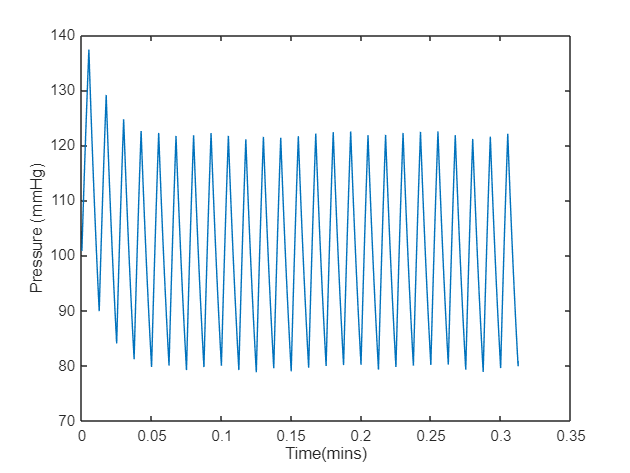

% Systemic arteries isolation implementation V1

clear;clc;close all
Psa=100; % Initial Condition for pressure in systemic arteries (mmHg)
Rs=17.5; % Resistance of the systemic circuit (mmHg/(L/min))
T=0.0125; % Time for 1 heart beat (min)
ts=0.0050; % Time for systole (min)
tmax= 0.002; % Time for max flow rate during systole (min) if using triangle wave
Qmax=14.14; % Max flow rate through aorta during systole (L/min)
Csa=0.001; % Compliance constant for systemic arteries (L/mmHg)
% Csa was fiddled with to achieve Psa of 120/80 mmHg

dt=0.0001; % Time step (min)
t=0:dt:25*T; % Vectorized time (min)

%% Solve Diff Eq
for k=1:length(t) % Go from beginning of time to end
    QAo=Qsquarewave(t(k),Qmax,T,ts); % Flow rate at any given point in time
    Psa=Psa+dt*(QAo-Psa/Rs)/Csa; % Pressure at any given point in time
    QAoplot(k)=QAo; % Output left heart flow through aortic valve
    Qsplot(k)=Psa/Rs; % Outplot flow through systemic circuit
    Psaplot(k)=Psa; % Output pressure into Psaplot for plotting later
    Vsaplot(k)=Psa*Csa; % Output volume into Vsaplot for plotting later
end

plot(t,Psaplot)
xlabel('Time(mins)')
ylabel('Pressure (mmHg)')

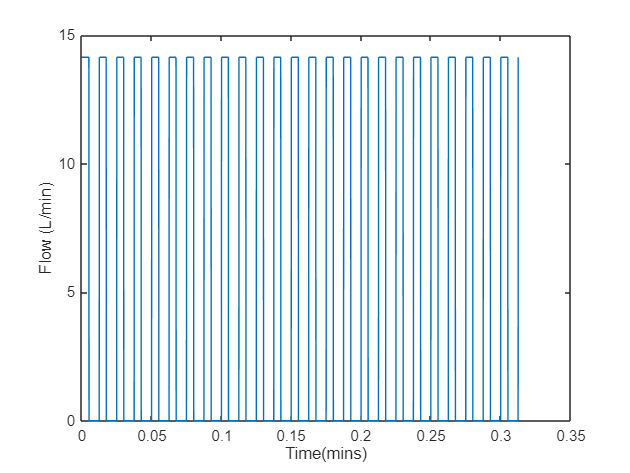

figure
plot(t, QAoplot)
xlabel('Time(mins)')
ylabel('Flow (L/min)')

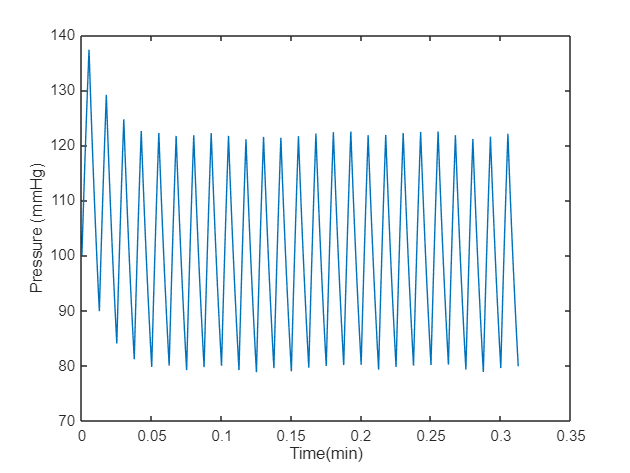

% Systemic arteries isolation implementation V2

clear;clc;close all
Psa=100; % Initial Condition for pressure in systemic arteries (mmHg)
Rs=17.5; % Resistance of the systemic circuit (mmHg/(L/min))
T=0.0125; % Time for 1 heart beat (min)
ts=0.0050; % Time for systole (min)
tmax= 0.002; % Time for max flow rate during systole (min) if using triangle wave
Qmax=14.14; % Max flow rate through aorta during systole (L/min)
Csa=0.001; % Compliance constant for systemic arteries (L/mmHg)
% Csa was fiddled with to achieve Psa of 120/80 mmHg

dt=0.0001; % Time step (min)
t=0:dt:25*T; % Vectorized time (min)

%% Solve Diff Eq
for k=1:length(t)-1 % Go from beginning of time to end
    QAo(k)=Qsquarewave(t(k),Qmax,T,ts); % Flow rate at any given point in time
    Psa(k+1)=Psa(k)+dt*(QAo(k)-Psa(k)/Rs)/Csa; % Pressure at any given point in time
end
plot(t,Psa)
xlabel('Time(min)')
ylabel('Pressure (mmHg)')

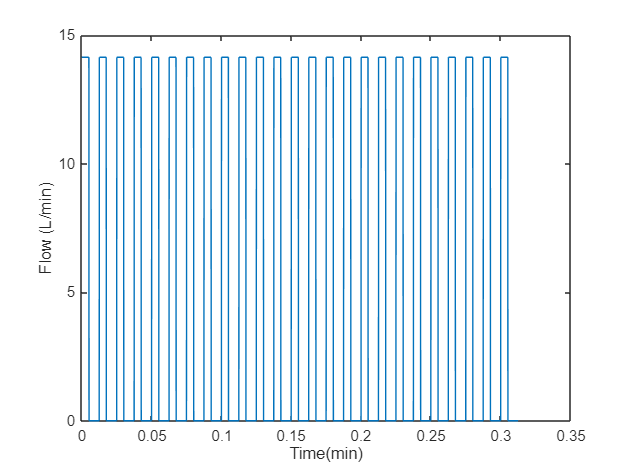

figure
plot(t(1:end-1),QAo)
xlabel('Time(min)')
ylabel('Flow (L/min)')

% Hemodynamics: dynamic heart compliance

function CV=CV_now(t,T,ts,tauS,tauD,CVS,CVD)
% Compliance of the Ventricle Testing
% CVS and CVD refer to the compliance of either the right or left
% ventricle during systole and diastole, respectively. CLVS, CRVS,
% CLVD, and CRVD.
% Remainder of cardiac cycle

tc=rem(t,T);
for ii=1:length(tc) % For every time point that’s in tc
    if tc(ii)<ts % If tc is less than ts, systole
        e=(1-exp(-tc(ii)/tauS))/(1-exp(-ts/tauS));
        CV(ii)=CVD*(CVS/CVD)^e;
    else % If tc is greater than ts, diastole
        e=(1-exp(-(tc(ii)-ts)/tauD))/(1-exp(-(T-ts)/tauD));
        CV(ii)=CVS*(CVD/CVS)^e;
    end
end
end

Full heart using this 6 diff eq's

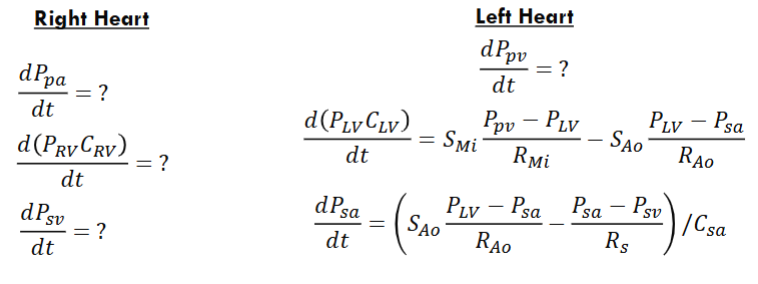

Full heart model (Left+Right+Artery+Veins) 

Equations to use